# ***Pregunta 2.***

Code: https://github.com/jorchmch/Lab4tae/blob/main/p2.m

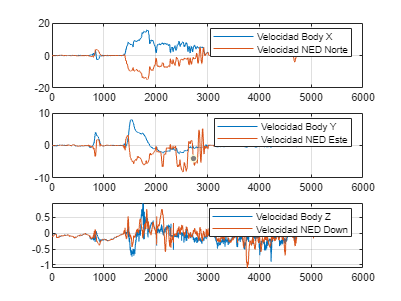

clc,clear;
close all;
%
% Unidades
% 
% yaw       :       Angulo de Euler "Yaw"               en  radianes
% pitch     :       Angulo de Euler "Pitch"             en  radianes
% roll      :       Angulo de Euler "yaw"               en  radianes
% velN      :       Velocidad NED respecto al Norte     en metros/segundo
% velE      :       Velocidad NED respecto al Este      en metros/segundo
% velD      :       Velocidad NED respecto al Down      en metros/segundo
% alt       :       Altitud                             en metros
% lon       :       Longitud                            en grados
% lat       :       Latitud                             en grados

load('datosActualizados.mat')

%  Pregunta 2

% Ned a Body
% Fossen ec. 2.18 
 tamDatos = length(yaw);

 a11 = 0;a12 = 0;a13 = 0;a21 = 0;a22 = 0;a23 = 0;a31 = 0;a32 = 0;a33 = 0;
 VelBody = zeros(tamDatos,3);

    for i=1:tamDatos
        
        a11 = cos(yaw(i,1)) * cos(pitch(i,1));
        a12 = sin(yaw(i,1)) * cos(pitch(i,1));
        a13 = -sin(pitch(i,1));    
    
        a21 = - sin(yaw(i,1)) * cos(roll(i,1)) + cos(yaw(i,1)) * sin(pitch(i,1)) * sin(roll(i,1));
        a22 = cos(yaw(i,1)) * cos(roll(i,1)) + sin(roll(i,1)) * sin(pitch(i,1)) * sin(yaw(i,1));
        a23 = sin(roll(i,1)) * cos(pitch(i,1));
    
    
        a31 = cos(roll(i,1)) * sin(pitch(i,1)) * cos(yaw(i,1)) + sin(roll(i,1)) * sin(yaw(i,1));
        a32 = - cos(yaw(i,1)) * sin(roll(i,1)) + sin(pitch(i,1)) * sin(yaw(i,1)) * cos(roll(i,1));
        a33 = cos(roll(i,1)) * cos(pitch(i,1));     
        
        Matriz = [[a11 a12 a13];[a21 a22 a23];[a31 a32 a33]];
        
        % Matriz Inversa
        % InvMatriz = inv(Matriz);
        InvMatriz = (Matriz);  % Para NED a Body no hay Inversa.
    
        % Producto con Matriz de Velocidad Errada
        VelMatrix = [velN(i,1);velE(i,1);velD(i,1)];
    
        VelBody(i,:) = (InvMatriz * VelMatrix)';
        
    end
    
    velBodyX = VelBody(:,1);
    velBodyY = VelBody(:,2);
    velBodyZ = VelBody(:,3);
    
    figure('Name','Velocidad en NED vs Body')
    subplot(311)
    plot(velBodyX);
    hold on
    plot(velN)
    legend('Velocidad Body X','Velocidad NED Norte')
    grid on
    subplot(312)
    plot(velBodyY);
    hold on
    plot(velE)
    legend('Velocidad Body Y','Velocidad NED Este')
    grid on
    subplot(313)
    plot(velBodyZ);
    hold on
    plot(velD)
    legend('Velocidad Body Z','Velocidad NED Down')
    grid on

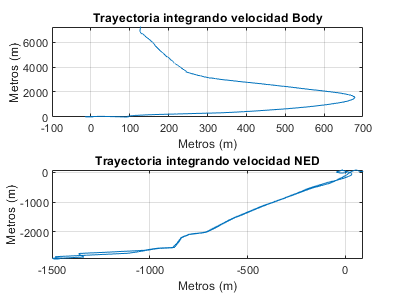

% Creacion de variables Tabletime
fs = 1/3; % Hz
timeArray = seconds((0:fs:fs*(tamDatos-1))');
yawTimeSeries = array2timetable(yaw,'RowTimes',timeArray);
pitchTimeSeries = array2timetable(pitch,'RowTimes',timeArray);
rollTimeSeries = array2timetable(roll,'RowTimes',timeArray);
latiTimeSeries = array2timetable(lat,'RowTimes',timeArray);
longTimeSeries = array2timetable(lon,'RowTimes',timeArray);
altiTimeSeries = array2timetable(alt,'RowTimes',timeArray);
velBodyXTimeSeries = array2timetable(velBodyX,'RowTimes',timeArray);
velBodyYTimeSeries = array2timetable(velBodyY,'RowTimes',timeArray);
velNedNTimeSeries = array2timetable(velN,'RowTimes',timeArray);
velNedETimeSeries = array2timetable(velE,'RowTimes',timeArray);

% Simulacion en Simulink y obtencion de datos de salida.
% Simulacion tamDatos/3 = 1739 seg.

p_2 = sim('trayectoria_desde_Velocidades.slx');

pos_x_Body = p_2.trayectoria(:,1);
pos_y_Body = p_2.trayectoria(:,2);
pos_x_NED = p_2.trayectoria(:,3);
pos_y_NED = p_2.trayectoria(:,4);

% Grafica de trayectorias recorrida
figure('Name','Trayectorias segun Marco de referencia')
subplot(211)
plot(pos_y_Body,pos_x_Body);
title('Trayectoria integrando velocidad Body')
grid on;
ylabel('Metros (m)');
xlabel('Metros (m)');
subplot(212)
plot(pos_y_NED,pos_x_NED);
title('Trayectoria integrando velocidad NED')
grid on;
ylabel('Metros (m)');
xlabel('Metros (m)');

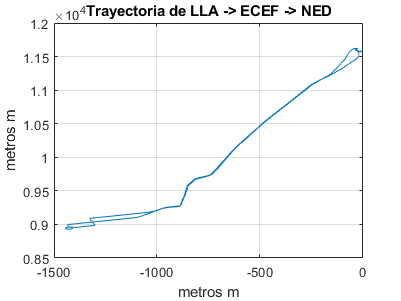


% Pregunta 3

p3 = sim('LLA_to_ECEF.slx');
lat0 = -16.4655103300000;
lon0 = -71.4932423200000;
alt0 = 2490.55500000000;
wgs84 = wgs84Ellipsoid('kilometer');

[xNor, yEas, zDow] = ecef2ned(p3.ECEF(:,1),p3.ECEF(:,2),p3.ECEF(:,3),lat0,lon0,alt0,wgs84);
figure
plot(yEas,xNor)
title('Trayectoria de LLA -> ECEF -> NED')
grid on
xlabel('metros m')
ylabel('metros m')


% Pregunta 4
